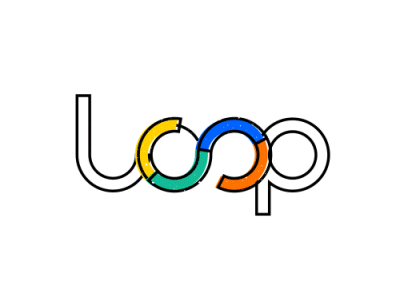

# `loop`

# ` - for`

`      - for index = values, statements, end executes a group of statements in a loop for a specified number of times. values has one of the following forms:`

`      - initVal:endVal — Increment the index variable from initVal to endVal by 1, and repeat execution of statements until index is greater than endVal.`

`      - initVal:step:endVal — Increment index by the value step on each iteration, or decrements index when step is negative.`

`      - valArray — Create a column vector, index, from subsequent columns of array valArray on each iteration. For example, on the first iteration, index =  -                          `

# ` - while`

`      - while expression, statements, end evaluates an expression, and repeats the execution of a group of statements in a loop while the expression is true. An expression is true when its result is nonempty and contains only nonzero elements (logical or real numeric). Otherwise, the expression is false.`

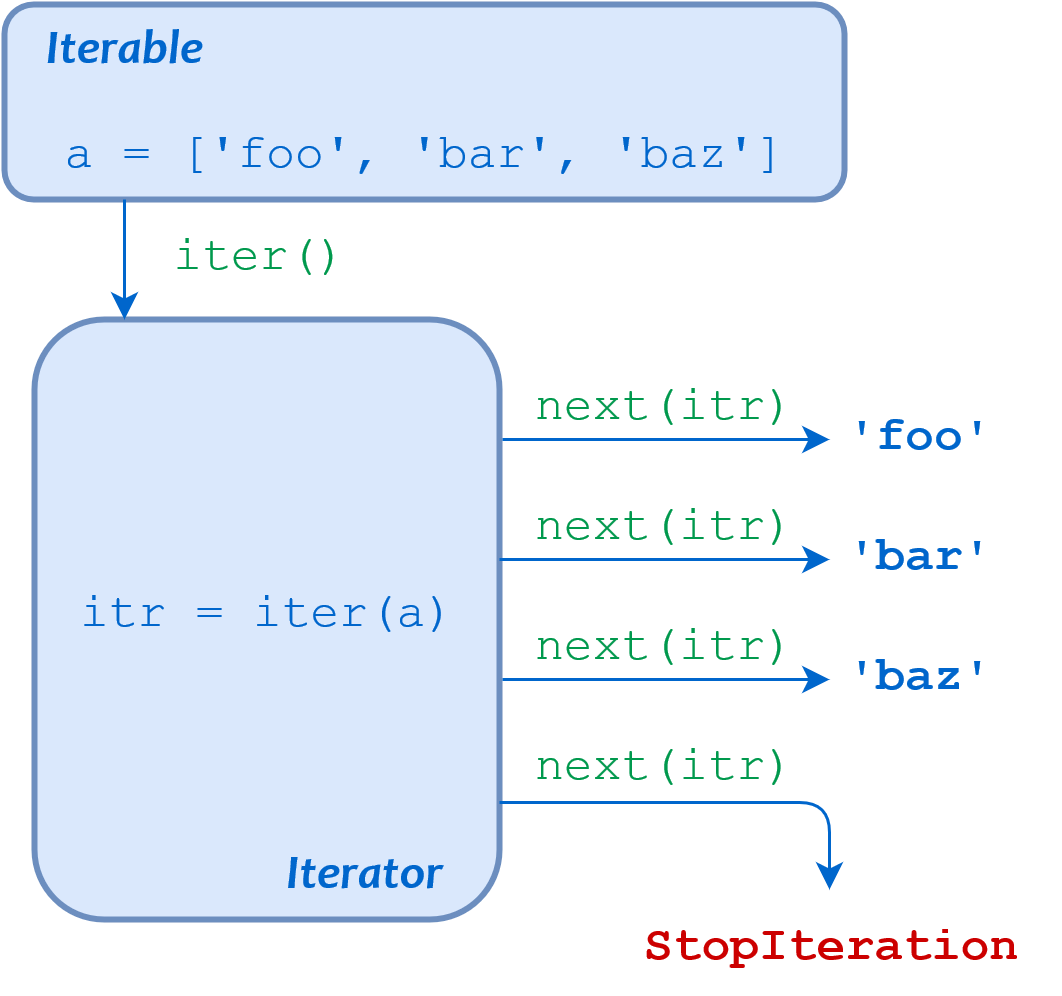

# `- for`

# `Ex`

for a = 10:15
 fprintf('value of a: %d\n', a);
end

value of a: 10
value of a: 11
value of a: 12
value of a: 13
value of a: 14
value of a: 15


# `Ex`


$$1+2+3+4+5+6+7+8+9+10$$


sum(1:10)

ans = 55


$$1+2+3+4+5+6+7+8+9+10$$


s = 0 ;
for i =  1:10
    s = s + i;
end
fprintf('sum is %d', s)

sum is 55

# `Ex`

n = 10;
for i = 1:n % The increment is 1
 disp(i^2)
end

     1

     4

     9

    16

    25

    36

    49

    64

    81

   100



# `Ex`


$$1\;\;,1\;,2\;,3\;,5\;,8\;,13\;,\;\;\ldotp \ldotp \ldotp \;\;\textrm{Fibonacci}$$


a(1) = 1;
a(2) = 1;
for i = 3 : 8
    a(i) = a(i-1) + a(i-2) ;
end 
num2str(a)

ans = '1   1   2   3   5   8  13  21'

# `Ex`

`Multiplication table`

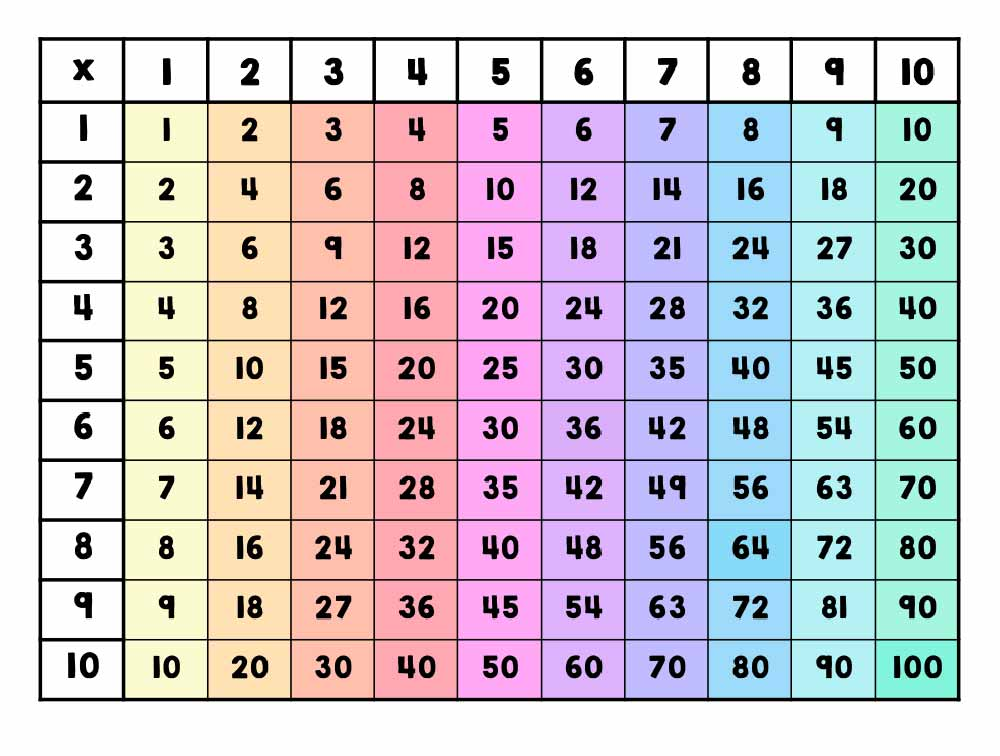

for i = 1:10
    for j = 1:10
        table(i, j) = i * j ;
    end
end
table

table =      1     2     3     4     5     6     7     8     9    10
     2     4     6     8    10    12    14    16    18    20
     3     6     9    12    15    18    21    24    27    30
     4     8    12    16    20    24    28    32    36    40
     5    10    15    20    25    30    35    40    45    50
     6    12    18    24    30    36    42    48    54    60
     7    14    21    28    35    42    49    56    63    70
     8    16    24    32    40    48    56    64    72    80
     9    18    27    36    45    54    63    72    81    90
    10    20    30    40    50    60    70    80    90   100


# `Ex`


$$n\;!\;=\;1\times 2\times 3\times 4\times \dots \times n$$


factor = 1;
for i = 1:4
    factor = factor * i;
end
disp(factor)

    24



factorial(4)

ans = 24

prod(4)

ans = 4

# `Ex`

# * 

# ** 

# *** 

# **** 

# ***** 

# ****** 

# *******

rows = 6;
tic
for R = 1:rows
   for s = 1:R
       fprintf( '*' );
   end
   fprintf(' \n' );
end

*

**

***

****

*****

******

toc   % time for loop

Elapsed time is 0.019838 seconds.


# `Ex`

` - Convert a Matrix into a Vector`

% Assume matrix M exists
M = randn(3)

M =    -0.0549    0.3502    0.2398
    0.9111    1.2503   -0.6904
    0.5946    0.9298   -0.6516


[r c] = size(M);
V = [ ];
for col = 1:c
    for row = 1:r
       V(end+1) = M(row,col);
    end
end
disp(num2str(V))

-0.054919     0.91113     0.59458      0.3502      1.2503     0.92979     0.23976    -0.69036    -0.65155


# `- while`

# `Ex`

z = 1;
while (z < 10)  %loop statement
       z = z*2   %loop body
end 

z = 2

z = 4

z = 8

z = 16

# `Ex`

d = 0;
while (d < 5)
      disp(d)
      d = d + 1;
end

     0

     1

     2

     3

     4



# `Exercises`

for i = 1.5: 0.2: 2.7
 disp(i)
end

    1.5000

    1.7000

    1.9000

    2.1000

    2.3000

    2.5000

    2.7000



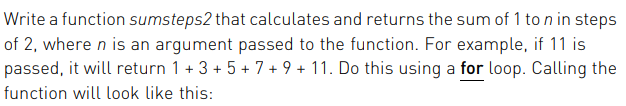

% Return  ->  1 + 3 + ... + n   -> EX.   n = 11
outsum = 0;
for i = 1: 2: 11
    outsum = outsum + i;
end
disp(outsum)

    36



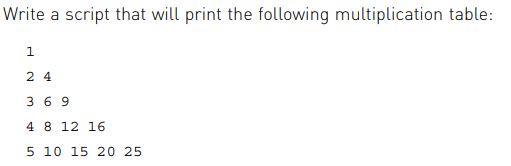

% Prints table
rows = 5 ;
for i = 1:rows
     for j = 1:i
        fprintf('%d ', i*j)
     end
    fprintf(' \n')
end

1 

2 4 

3 6 9 

4 8 12 16 

5 10 15 20 25 

n =  5 ;
for i = 1:n
    a = 1:i;
    vec = i*a;
    disp(vec)
end

     1

     2     4

     3     6     9

     4     8    12    16

     5    10    15    20    25



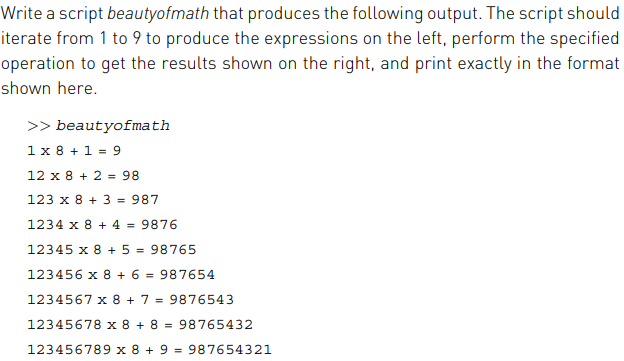

numleft = 0;
for i = 1:9
 numleft = numleft * 10 + i;
 ansnum = numleft * 8 + i;
 fprintf('%d x 8 + %d = %d\n', numleft, i, ansnum)
end

1 x 8 + 1 = 9
12 x 8 + 2 = 98
123 x 8 + 3 = 987
1234 x 8 + 4 = 9876
12345 x 8 + 5 = 98765
123456 x 8 + 6 = 987654
1234567 x 8 + 7 = 9876543
12345678 x 8 + 8 = 98765432
123456789 x 8 + 9 = 987654321


# `Bubblesort`

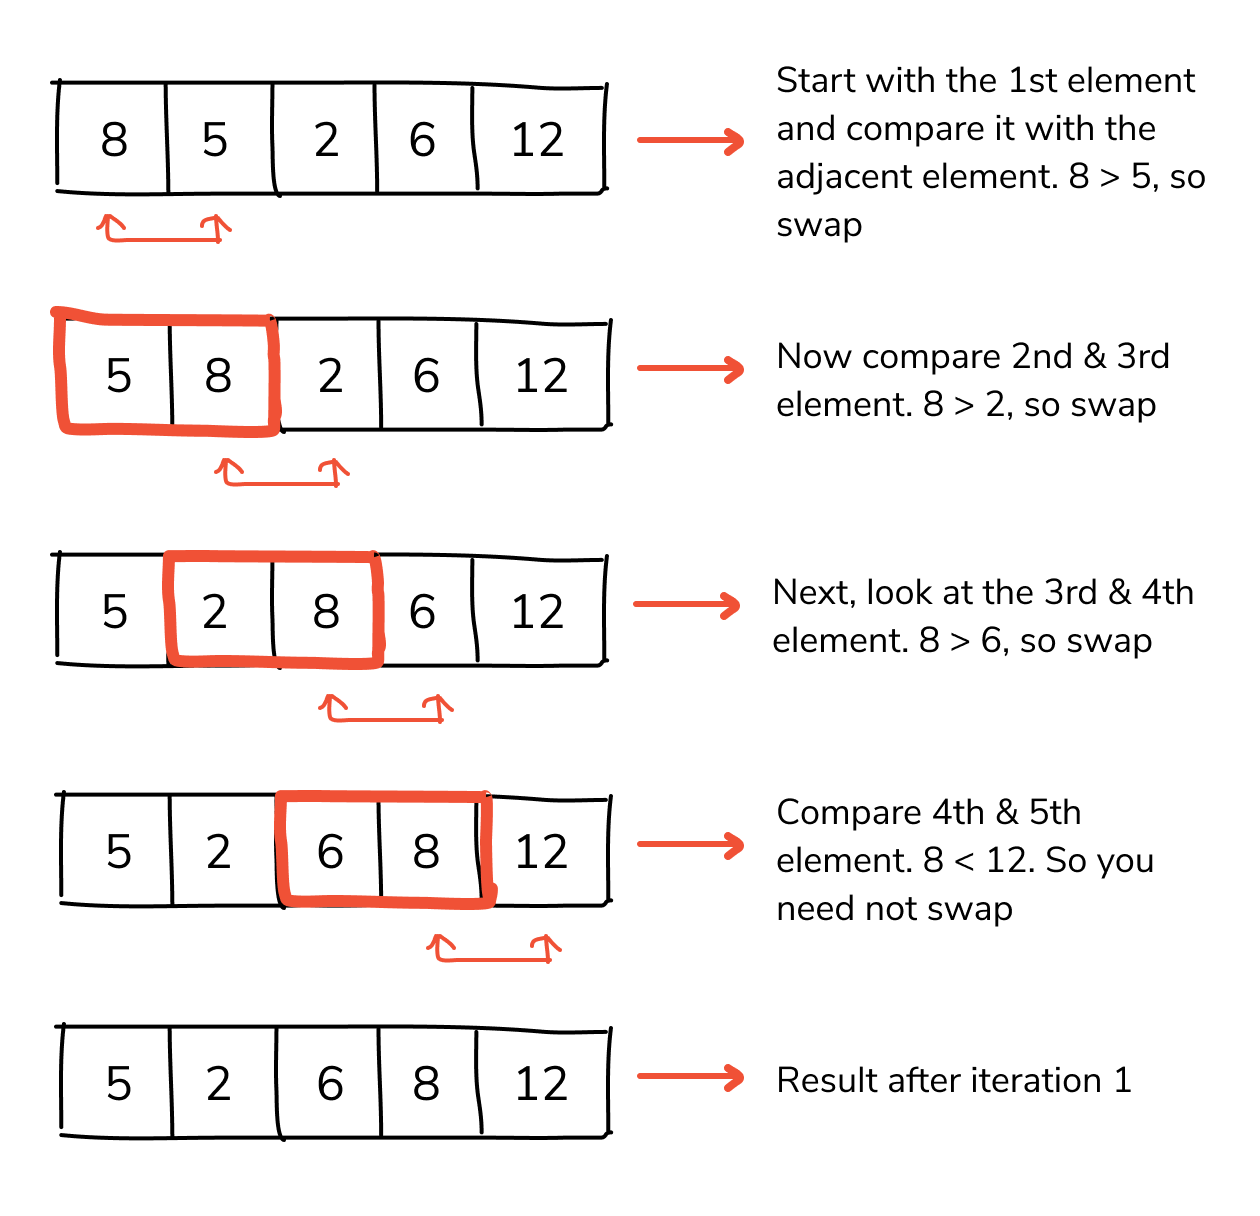

% type 1
a = [-10, 100, 5, 3, 64, 1, -3, 23, 32, 78] ;
sort(a)

ans =    -10    -3     1     3     5    23    32    64    78   100


% type 2
n = length(a);
for i = 1: n-1 
    for j = 1: n-i          
        if a(j) > a(j + 1)    %  <   or   >
        m = a(j);
        a(j) = a(j + 1);
        a(j + 1) = m;
        end
   end
end
B = a;
B

B =    -10    -3     1     3     5    23    32    64    78   100


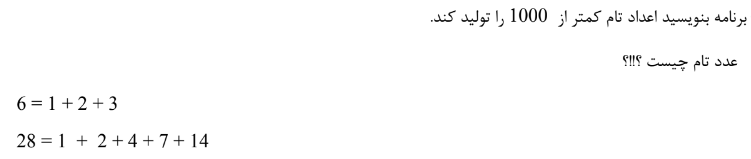

for k = 1:1000
% factors = divisors(k);
   D = 1:k ;
   factors = D(rem(k,D) == 0 ) ;
   factors(end) = [] ;
     if sum(factors) == k
        disp(k)
    end
end

     6

    28

   496



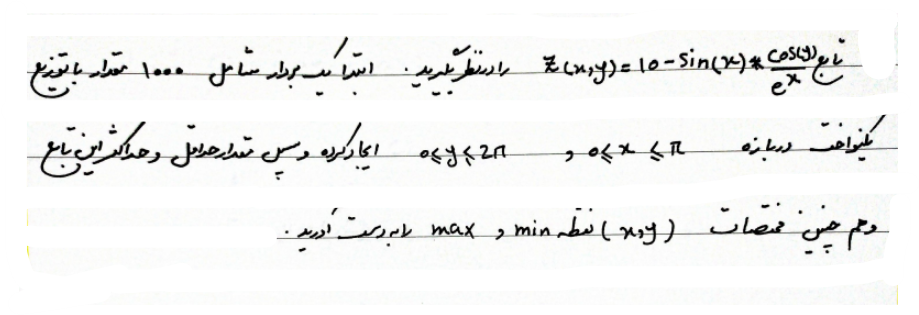

x = linspace(0 ,pi ,1000) ;
y = linspace(0 ,2*pi ,1000) ;
[X, Y] =meshgrid(x ,y) ;
z = 10 - sin(X).*cos(Y)./exp(X) ;
maximum = max(max(z)) ;
minimum = min(min(z)) ;
[xmax , ymax] = find(z == maximum) ;
[xmin , ymin] = find(z == minimum) ;
maxcord = [x(xmax) ; y(ymax)]

maxcord =     1.5692    1.5724
    1.5724    1.5724


mincord = [x(xmin) ; y(ymin)]

mincord =          0    3.1416
    1.5724    1.5724


`-------------------------------------------------------------------------------------------`

`. `[`Korosh Agha Mohammad Ghasemi `](https://koroshkorosh1.github.io/korosh.github.io/)`. `